# Detecting circles

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity. 

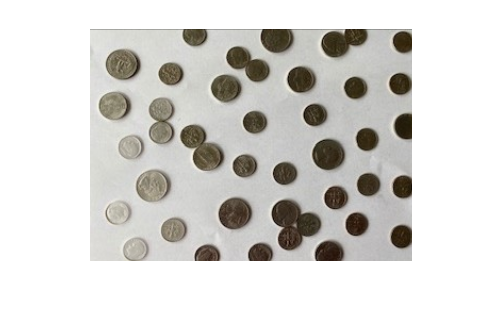

coins = imread("./images/change.png");
imshow(coins)

## Task 1, 2, and 4

In this practice, you will compute the value of the change in the image `coins`. Start by finding the positions of the coins using the `imfindcircles` function.

`[``centers``,``radii``]` `=` `imfindcircles``(``I``,``[``rmin` `rmax``])`

Using this syntax, circles in `I` will be detected with radii in the range specified by the two-element vector `[``rmin` `rmax``]`.

All of these radii are between 6 and 20 pixels.

These vectors were empty because, by default, `imfindcircles` detects circular objects that are brighter than the background. You can set the `"ObjectPolarity"` to `"dark"` to detect objects that are darker than the background.

`imfindcircles``(``...,` `"ObjectPolarity"``,``"dark"` `)`

A few of the lighter coins were not detected with the default settings. Like other detection techniques, you can tune the circle detection parameters.

`imfindcircles``(``...,` `"Sensitivity"``,``factor` `)`

The `Sensitivity` parameter ranges from 0 to 1 with a default value of 0.85. Higher values will detect more circles.

[c,r] = imfindcircles(coins, [6 20],...
    "ObjectPolarity", "dark",...
    "Sensitivity", 0.9)

c =   239.3527  125.9285
  212.4186   51.2668
  146.1333  185.1186
   82.0789   45.5272
  313.6631  159.0000
  246.5070  169.5107
  226.0000   86.5129
  137.4493   59.8741
  195.7685  145.0645
  245.6082   15.6627


r =    15.9766
   13.9570
   16.4397
   12.1669
   11.3845
   11.8893
   11.7924
   14.6108
   11.9820
   13.6433


## Task 3

Circles were found in the last call to `imfindcircles`, but were all the coins accurately located? Visualize them to find out.

`viscircles``(``centers``,``radii``)``;`

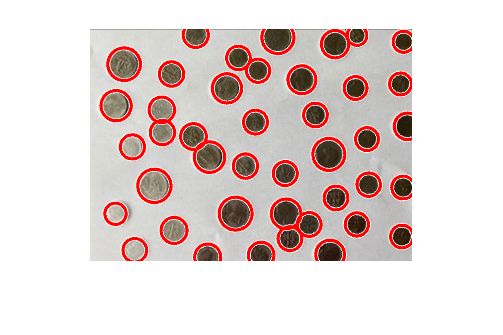

imshow(coins)
viscircles(c, r);

## Task 5

Now that you have found all the coins, you can classify them and compute the total value. The dimes are the smallest with diameters of less than 13 pixels.

idxd = r < 13;

## Task 6

To evaluate whether or not 13 pixels was the right radii cutoff for dimes, you can visualize the corresponding circles. To extract the subset of the radii based on the logical index variable, `idxd`, you can use logical indexing.

`r``(``idxd``)`

The centers have two dimensions and you need to extract both.

`c``(``idxd``,:``)`

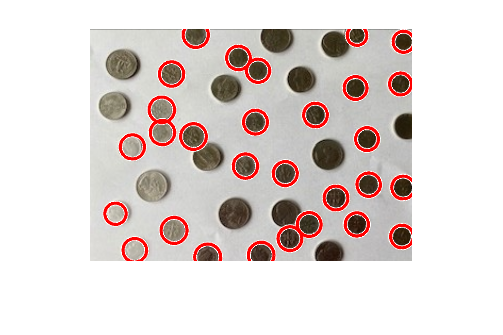

imshow(coins);
viscircles(c(idxd, :), r(idxd));

## Task 7

You can also compute the total value of the dimes by counting them and multiplying the result by 0.1, the value of a dime in USD. To count the number of nonzero objects in an array, you can use the `nnz` function.

nDimes = nnz(idxd)

nDimes = 29

valueDimes = nDimes*0.1

valueDimes = 2.9000